# Boat stabilizer - Model parameters

In this script we'll define numeric values for the parameters used to characterise the boat stabilization system. 

- These parameters will be used in the **Simullink** model 

Recall the main elements of the system as shown in Figure 1 below:

  **Figure 1:   The gyroscopic boat stabilizer**

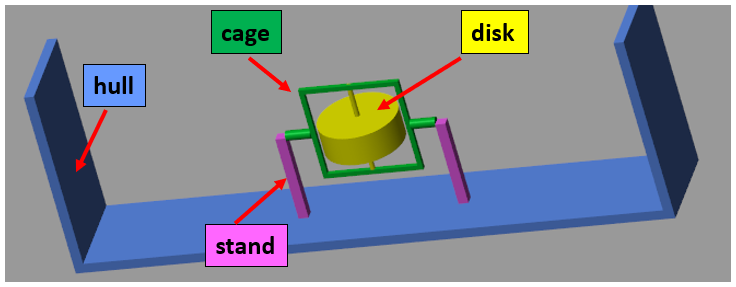 

 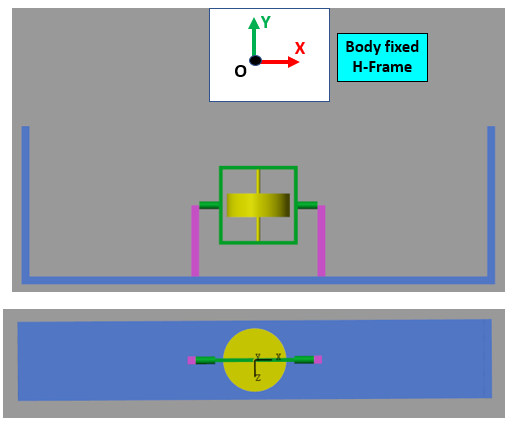

## Defining the geometry notation

We'll utilise the following length symbols

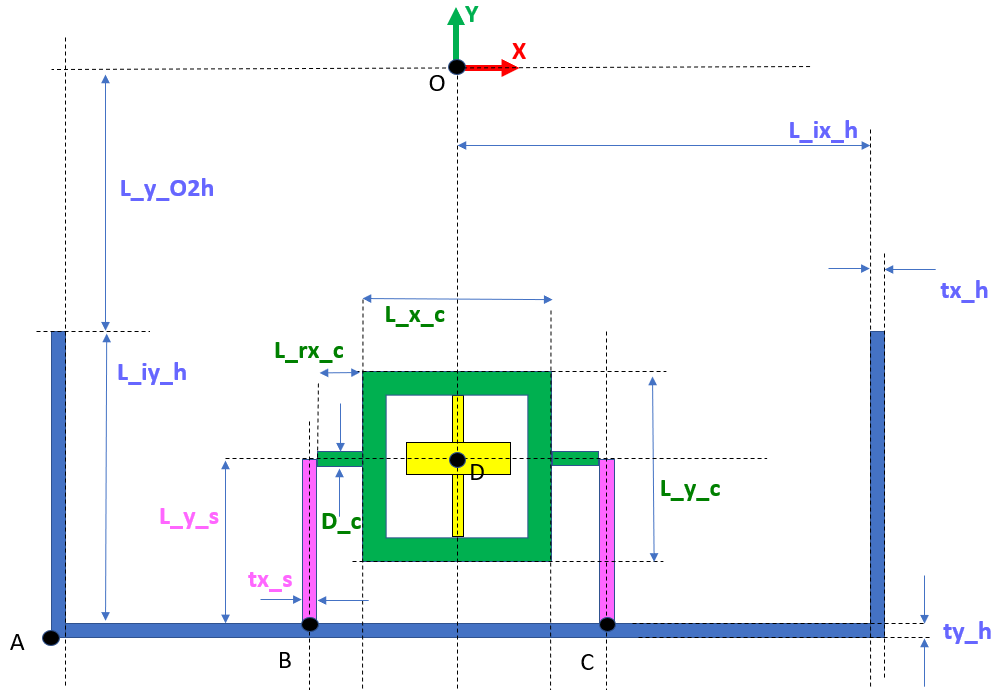

### cage params:

cage.Lx = 1;
cage.tx = 0.05;
cage.Ly = 1;
cage.ty = 0.05;
cage.tz = 0.05;
cage.D  = 0.1;
cage.L_rx = 0.25;
cage.density = 0.01; %1000;

### disk params:

disk.shaft_D = 0.05;
disk.shaft_L = cage.Ly;
disk.shaft_density = 0.1;
disk.D       = 0.8;
disk.L       = 0.3;
disk.density = 5000; %1000;

### stand params:

stand.Ly = 1.0;
stand.tx = 0.1;
stand.tz = 0.1;
stand.density = 0.1; %1000;

### hull params:

hull.tx      = 0.1;
hull.L_ix    = 2.9;
hull.ty      = 0.1;
hull.L_iy    = 1.9;
hull.tz      = 1.0; %2.0;
hull.L_y_O2h = 1.0;
hull.density = 1000;


### Points of interest:

my_points.A_rel2O = [-1*(hull.L_ix + hull.tx),  ...
                     -1*(hull.L_y_O2h + hull.L_iy + hull.ty), 0];
                 
my_points.B_rel2O = [-1*(cage.Lx/2 + cage.L_rx  + stand.tx/2), ...
                      (my_points.A_rel2O(2) + hull.ty),   0];

my_points.C_rel2O = [-1*(my_points.B_rel2O(1)), ...
                      (my_points.A_rel2O(2) + hull.ty),   0];  
                  
my_points.B_rel2A =  my_points.B_rel2O - my_points.A_rel2O;
my_points.C_rel2A =  my_points.C_rel2O - my_points.A_rel2O;

my_points.D_rel2O = [0, (my_points.B_rel2O(2) + stand.Ly), 0];

## Compute the mass and Inertia properties for each component of the system

For the hull, cage and disk, we'll compute the following:

- `com_sys_rel_O : `the co-ordinates of the body's CoM relative to the body fixed **H-frame**

- `           Ig : `the Inertia matrix of the body about the body's CoM

- `         Mass : `the body's mass

###  for the hull

 my_res  = LOC_calc_Ig_and_comrelO_for_hull(hull)

my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 980


 hull.calcs = my_res;

### for the disk

 my_res =  LOC_calc_Ig_and_comrelO_for_disk(disk, hull, stand)

my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 753.9824


 disk.calcs = my_res;

### for the cage

my_res =  LOC_calc_Ig_and_comrelO_for_cage(cage, disk)

my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 1.3427e-04


cage.calcs = my_res;

# Local Subfunctions only beyond this point

### Compute rG and IG for the hull

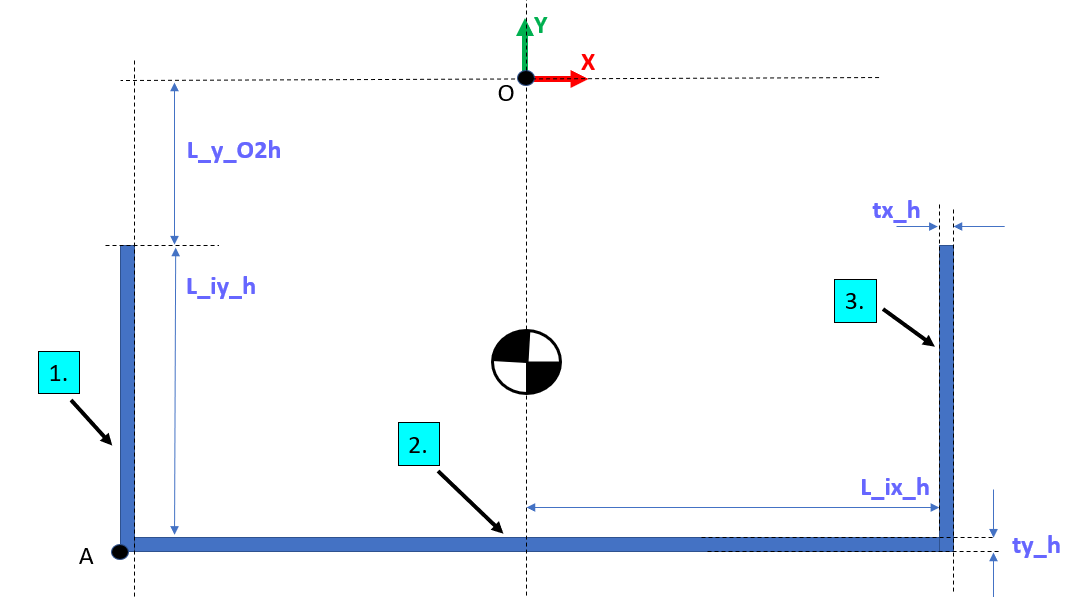

function my_res =  LOC_calc_Ig_and_comrelO_for_hull(hull)
    
    % compute the masses of each prism
    m1 = hull.tz * hull.tx * (hull.L_iy + hull.ty) * hull.density;
    m3 = m1;
    m2 = hull.tz * hull.ty * (2*hull.L_ix) * hull.density;
    m_total = m1 + m2 + m3;
    
    % Compute CoM relative to A first, then compute Com relative to O
    com_rect_1_rel_A = [hull.tx/2,                             (hull.L_iy + hull.ty)/2,    0 ];
    com_rect_3_rel_A = [(2*hull.L_ix  + hull.tx + hull.tx/2),  (hull.L_iy + hull.ty)/2,    0 ];
    com_rect_2_rel_A = [(hull.tx + hull.L_ix),                  hull.ty/2,                 0 ];
    com_sys_rel_A    = (m1*com_rect_1_rel_A   +   m2*com_rect_2_rel_A   +   m3*com_rect_3_rel_A) / m_total;
    com_sys_rel_O    = com_sys_rel_A +  [-1*(hull.L_ix + hull.tx),  -1*(hull.L_y_O2h + hull.L_iy + hull.ty),  0];
    com_sys_rel_O    = com_sys_rel_O(:);
    
    % now for the accumulation of inertias
    % First compute the inertias of each prism about their own Com
    [Lx, Ly, Lz, density] = deal(hull.tx, (hull.L_iy + hull.ty), hull.tz, hull.density);
    Ig_1 =  LOC_calc_Ig_for_prism(Lx, Ly, Lz, density);
    
    [Lx, Ly, Lz, density] = deal(2*hull.L_ix, hull.ty, hull.tz, hull.density);
    Ig_2 =  LOC_calc_Ig_for_prism(Lx, Ly, Lz, density);
    
    Ig_3 = Ig_1;
    
    % Next, transform co-ordinates known in the A-frame to co-ordinates in the ComSys-frame
    %   r_rel_comSys = r_rel_A - com_sys_rel_A
    
    com_rect_1_rel_comSys = com_rect_1_rel_A - com_sys_rel_A;
    com_rect_2_rel_comSys = com_rect_2_rel_A - com_sys_rel_A;
    com_rect_3_rel_comSys = com_rect_3_rel_A - com_sys_rel_A;
    
    % and now apply the Parallel axis theorm
    I1_desired = LOC_calc_I_using_parallel_axis_theorem( com_rect_1_rel_comSys,  Ig_1, m1 );
    I2_desired = LOC_calc_I_using_parallel_axis_theorem( com_rect_2_rel_comSys,  Ig_2, m2 );
    I3_desired = LOC_calc_I_using_parallel_axis_theorem( com_rect_3_rel_comSys,  Ig_3, m3 );
    
    % and accumulate the inertis
    Ig = I1_desired + I2_desired + I3_desired;

    % take care of the output
    my_res.com_sys_rel_O = com_sys_rel_O;
    my_res.Ig            = Ig;
    my_res.mass          = m_total;
end

### Compute Ig for a rectangular prism

- REF:  "Vector mechanics for Engineers" - F.P,Beer, E.R.Jonston

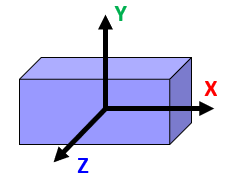

function Ig = LOC_calc_Ig_for_prism(Lx, Ly, Lz, density)
    m       = Lx * Ly * Lz * density;
    
    Ig      = zeros(3);
    
    Ig(1,1) = (Ly^2  +  Lz^2)*m/12;
    Ig(2,2) = (Lx^2  +  Lz^2)*m/12;
    Ig(3,3) = (Lx^2  +  Ly^2)*m/12;
end

### Compute I about a desired frame using the Parallel access theorm

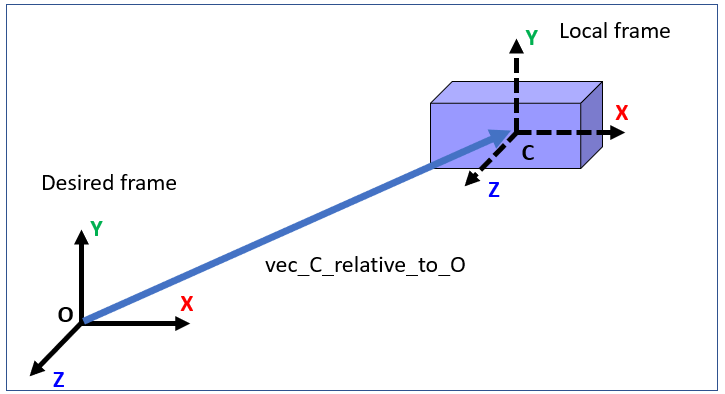

function I_desired = LOC_calc_I_using_parallel_axis_theorem( vec_from_desired_frame_to_local_com,  Ig_local, mass )

    x_c  =  vec_from_desired_frame_to_local_com(1);
    y_c  =  vec_from_desired_frame_to_local_com(2);
    z_c  =  vec_from_desired_frame_to_local_com(3);
            
   A     =  [ (y_c^2 + z_c^2),         -x_c*y_c,         -x_c*z_c;
                     -x_c*y_c,  (x_c^2 + z_c^2),         -y_c*z_c;
                     -x_c*z_c,         -y_c*z_c,  (x_c^2 + y_c^2);
            ];
        
    I_desired = Ig_local +  (mass * A);

end

### Compute rG and IG for the Disk

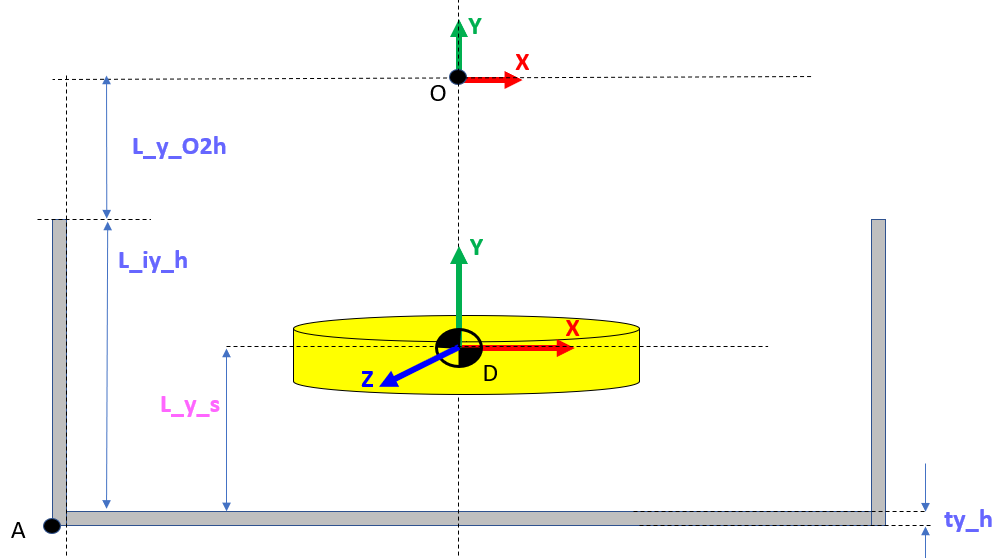

function my_res =  LOC_calc_Ig_and_comrelO_for_disk(disk, hull, stand)
    m_disk        = disk.density * disk.L * pi * (disk.D/2)^2;
    com_sys_rel_O = [0;  -1*(hull.L_y_O2h + hull.L_iy - stand.Ly);  0];
    Ig_disk       = LOC_calc_Ig_for_cylinder( (disk.D/2), disk.L, disk.density);
    
    % what about the shaft
    m_shaft  = disk.shaft_density * disk.shaft_L * pi *  (disk.shaft_D/2)^2;
    Ig_shaft = LOC_calc_Ig_for_cylinder( (disk.shaft_D/2), disk.shaft_L, disk.shaft_density);
    
    % and the totals - NOTE: we're double dipping on the mass and inertia
    % for the intersection of the shaft and disk. - but we'll do the same for Simscape too. 
    mass = m_disk + m_shaft;
    Ig   = Ig_disk + Ig_shaft;
    
    % take care of the output
    my_res.com_sys_rel_O = com_sys_rel_O;
    my_res.Ig            = Ig;
    my_res.mass          = mass;
end

### Compute Ig for a cylinder

- REF:  "Vector mechanics for Engineers" - F.P,Beer, E.R.Jonston

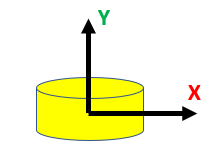

function Ig = LOC_calc_Ig_for_cylinder(r, L, density)
    m       = pi * (r^2) * L * density;    
    Ig      = zeros(3);
    
    Ig(1,1) = m * (3*r^2  + L^2) / 12;
    Ig(2,2) = m * (r^2) / 2;
    Ig(3,3) = Ig(1,1);
end

### Compute rG and IG for the Cage

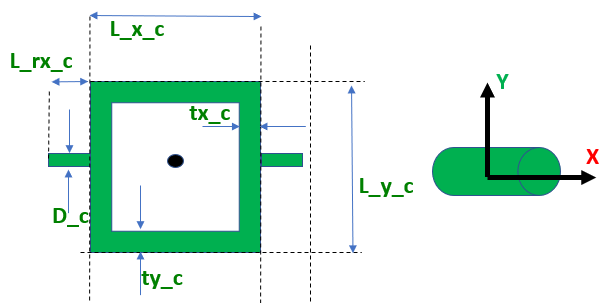

function my_res = LOC_calc_Ig_and_comrelO_for_cage(cage, disk)
    
    Lx_outer = cage.Lx;
    Lx_inner = cage.Lx - 2*cage.tx;
    Ly_outer = cage.Ly;
    Ly_inner = cage.Ly - 2*cage.ty;
    
    tmp_area_outer = Lx_outer * Ly_outer;
    tmp_area_inner = Lx_inner * Ly_inner;
    area           = tmp_area_outer - tmp_area_inner;
    mass           = area * cage.tz * cage.density;
    
    Ig_outer = LOC_calc_Ig_for_prism(Lx_outer, Ly_outer, cage.tz, cage.density);
    Ig_inner = LOC_calc_Ig_for_prism(Lx_inner, Ly_inner, cage.tz, cage.density);
    Ig       = Ig_outer - Ig_inner;
    
    % add the mass and inertias of the 2 rods(shafts)
    mass_of_1_shaft   = cage.density * cage.L_rx * pi * (cage.D/2)^2;
    mass_of_2_shafts  = 2 * mass_of_1_shaft;
    
    r                 = cage.D/2;
    Ig_rod_LEFT       = zeros(3);
    Ig_rod_LEFT(1,1)  = 0.5 * mass_of_1_shaft * r^2;
    Ig_rod_LEFT(2,2)  = (1/12) * mass_of_1_shaft * ( 3*r^2 + cage.L_rx^2 );
    Ig_rod_LEFT(3,3)  = (1/12) * mass_of_1_shaft * ( 3*r^2 + cage.L_rx^2 );    
    
    Ig_rod_RIGHT      = Ig_rod_LEFT;
    
    vec_Ig_rod_LEFT_rel_to_cage_CoM  = [-(cage.L_rx/2 + cage.Lx/2),0,0];
    vec_Ig_rod_RIGHT_rel_to_cage_CoM = [ (cage.L_rx/2 + cage.Lx/2),0,0];
    I_rod_LEFT_about_cage_CoM        = LOC_calc_I_using_parallel_axis_theorem( vec_Ig_rod_LEFT_rel_to_cage_CoM,   Ig_rod_LEFT,  mass_of_1_shaft );
    I_rod_RIGHT_about_cage_CoM       = LOC_calc_I_using_parallel_axis_theorem( vec_Ig_rod_RIGHT_rel_to_cage_CoM,  Ig_rod_RIGHT, mass_of_1_shaft );
    
    % and the totals
    mass = mass  +  mass_of_2_shafts;
    Ig   = Ig    +  I_rod_LEFT_about_cage_CoM  +  I_rod_RIGHT_about_cage_CoM;    
        
    % take care of the output
    my_res.com_sys_rel_O = disk.calcs.com_sys_rel_O;
    my_res.Ig            = Ig;
    my_res.mass          = mass;
    

end